 ppt_sif_bin.mat
 ppt_sm_bin.mat
 ppt_vod-c_bin.mat
 ppt_vod-x_bin.mat
 ppt_vod_bin.mat
 spi_sif_bin.mat
 spi_sm_bin.mat
 spi_vod-c_bin.mat
 spi_vod-x_bin.mat
 spi_vod_bin.mat


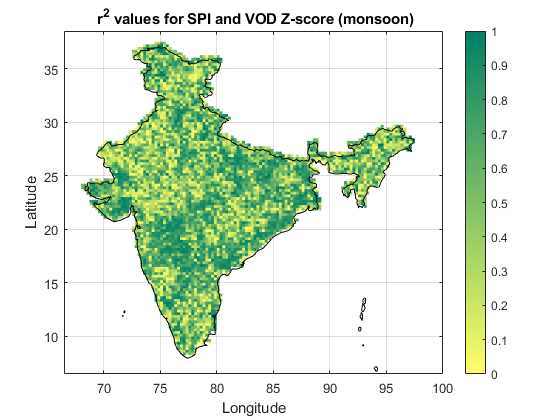

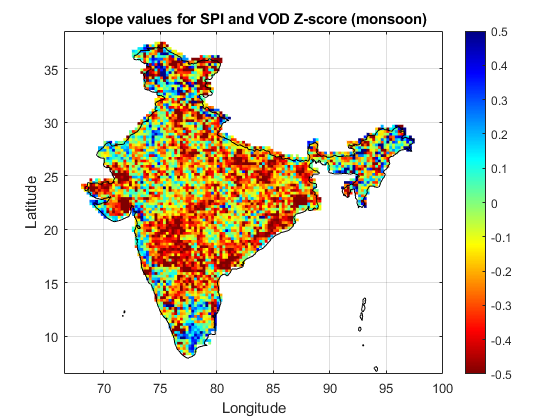

%USE steps
% check path of files my_folder (first- without lag, second -with lag)
% check index-2 (line 12 without lag and line 15-17 with lag )one has to be commented. and run
clear all
my_folder=fullfile("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results",'*.mat');
% my_folder=fullfile("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_1lag_result",'*.mat');%lag
theFiles=dir(my_folder);
for i =1:length(theFiles)
    
    fileName=theFiles(i).name;
    index_1=upper(fileName(1:3));
    index_2=upper(strip(fileName(4:end-8),"both","_"));%without lag
    
    %{
    index_2=upper(strip(fileName(4:end-13),"both","_"));%lag
    lag=strip(fileName(end-12:end-8),"both","_");%lag
    lag_title=lag(1:1)+"m "+"lag";%lag
    %}
% 
    fprintf(' %s\n' , fileName);
    fullpath=fullfile(theFiles(i).folder,fileName);

    d=load(fullpath);
    z_r=d.res(:,:,3);
    z_s=d.res(:,:,1);
    
%     correlation plot
    data=z_r;
    
    lat=data(2:130,1,1);
    lon=data(1,2:136,1)';
    crop1=(data(2:130,2:136,1));
    f=figure(1);
    slp=pcolor(lon,lat,crop1);
    slp.EdgeColor='none';
    xlabel('Longitude'); % Labelling x axis 
    ylabel('Latitude'); % Labelling y axis
    title(" r^2 values for "+ index_1 +" and "+ index_2 +" Z-score (monsoon)"); % Putting title to the figure
%     title(" r^2 values for "+ index_1 +" and "+ index_2 +" Z-score (monsoon "+lag_title+")");%lag
    colormap(flipud(summer)) % Setting a color scheme
    hcb1=colorbar; % Showing the scheme on a scale
    caxis([0 1])
    grid on % Showing grid lines
    hold on % Starting a new plot on same figure retaining the former
    geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
    saveas(f,"E:\MTP2\MTP2 final results\Automate_plot\monsoon\"+lower(index_2)+"\r2 "+index_1+"_"+index_2+".jpg");
%     saveas(f,"E:\MTP2\MTP2 final results\Automate_plot\monsoon\"+lower(index_2)+"\r2 "+index_1+"_"+index_2+" "+lag+".jpg");
   
%     slope plot
    data=z_s;
    
    lat=data(2:130,1,1);
    lon=data(1,2:136,1)';
    crop1=(data(2:130,2:136,1));
    f=figure(2);
    slp=pcolor(lon,lat,crop1);
    slp.EdgeColor='none';
    xlabel('Longitude'); % Labelling x axis 
    ylabel('Latitude'); % Labelling y axis
    title(" slope values for "+ index_1 +" and "+ index_2 +" Z-score (monsoon)"); % Putting title to the figure
%     title(" r^2 values for "+ index_1 +" and "+ index_2 +" Z-score (monsoon "+lag_title+")");%lag
    colormap(flipud(jet)) % Setting a color scheme
    hcb1=colorbar; % Showing the scheme on a scale
    caxis([-0.5 0.5])
    %title(hcb1,'(in m3/m3)') % Titling a colorbar
    grid on % Showing grid lines
    hold on % Starting a new plot on same figure retaining the former
    geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
    saveas(f,"E:\MTP2\MTP2 final results\Automate_plot\monsoon\"+lower(index_2)+"\slope "+index_1+"_"+index_2+".jpg");
%     saveas(f,"E:\MTP2\MTP2 final results\Automate_plot\monsoon\"+lower(index_2)+"\slope "+index_1+"_"+index_2+" "+lag+".jpg");


end